# Complete Beam Model

This script computes the total response of any cantilever beam model created in the Beam Designer GUI. 

## Import beam model

First, import a beam profile by loading an appropriate .mat file. This file may either be located in your working directory, or you can choose from one of the files in the Beam Profiles folder. This action will load a variable called "model" into your workspace. This is a struct containing various properties of the mechanical system, including the various dimensions of the beam, piezos, and retroreflectors, as well as some preliminary dynamics calculations. These calculations include the dynamic matrices: M, C, K, and A. The calculations also include the first *n* natural frequencies specified. 

clear
load("Beam Profiles/1DOF.mat");

## Specify Simulation Time

Enter the total elapsed time that this simulation should compute for. It will solve in time-steps of the driving frequency/16. 

sim_time = 1;       % sec

## Forcing terms

In this section, you can specify the driving frequency and amplitude of the system. Based on these inputs, the force that the piezo applies to the beam is calculated here. The voltage amplitude should be a number between +/- 10 Volts. This is the voltage output from a D/A converter. This amplitude is scaled based on the amplification factor on the piezo amplifier (it is a factor of 20). 

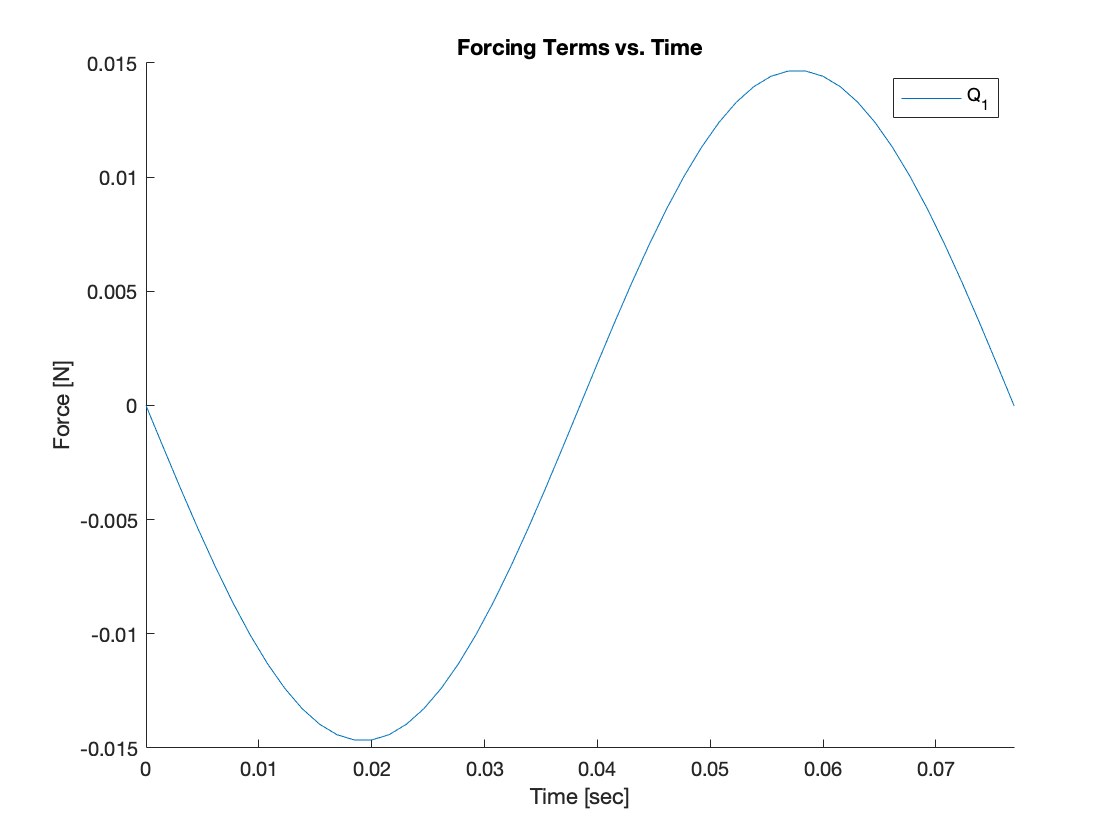

frequency = 13;       % Hz
amplitude = 1;       % V
phase = 0;           % Degrees
amplitude = amplitude*20;               % Scale to match power amplifier
period = 1/frequency;                   % Calculate period of driving frequency
fs = 50/period;                         % Define sampling frequency [Hz]
t_domain = (0:1/fs:sim_time);           % Linear time domain for the whole simulation
Q = @(t) piezo_signal(t,amplitude,frequency,phase).*getQ(model); % Create a function handle for the forcing term
Q_eval = Q(t_domain)';                  % Evaluate the piezo force for one period
figure;                                 % Create a figure 
hold on;                                % Allow multiple plots
plot(t_domain, Q_eval);                 % Plot the piezo force vs. time
for mode = 1:model.n                    % For each mode...
    label_mode = ["Q_",string(mode)];   %   Create an array with a label
    labels{mode} = join(label_mode,""); %   Join the array into one string and add to cell array  
end                                     %
legend(labels);                         % Add a legend using the array of labels 
clear labels                            % Clear for reuse later
title("Forcing Terms vs. Time");        % Add a title
xlim([0 period]);                       % Set x limits
xlabel("Time [sec]");                   % Label the x axis
ylabel("Force [N]");                    % Label the y axis

if model.units == "English"             % If the units are english...
    ylabel("Force [lbf]");              %      Change label to pounds
end

## Obtaining the Solution

Next, the state space is solved using ode45() to obtain the solution in generalized coordinates. The results are plotted below.

odeStep = 1; % Number of ODE solves
[t, Z] = modalODEcompute(model, t_domain, Q_eval, odeStep);

## Change Plotting Units

Use the toggle switch to plot in inches or micrometers:

um = true;

## Plotting Generalized Displacements

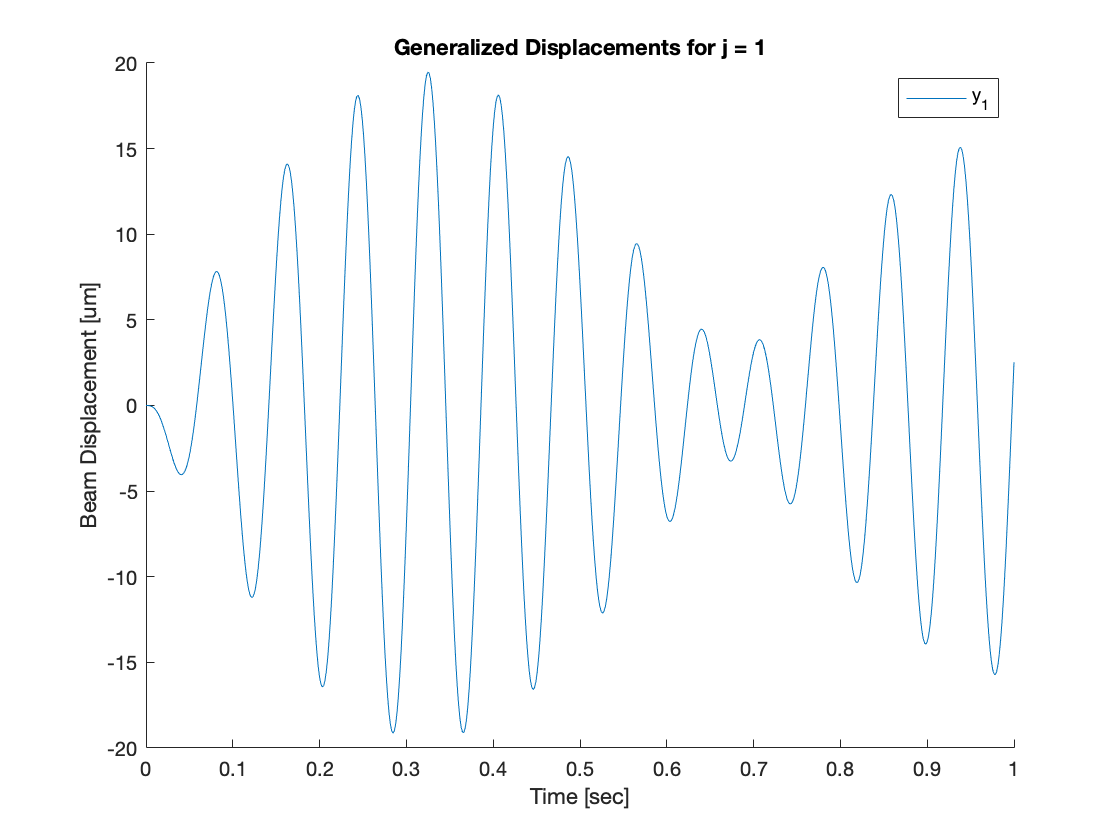

figure;                                                           % Create new figure
hold on;                                                          % Allow multiple plots
multiple = 1;                                                     % Initialize
if ~um && model.units == "English"                                % If um was not checked and units are english
    ylabel("Beam Displacement [in]");                             %     Assign y label 
    multiple = 12;                                                %     Multiply by 12 to get from ft to inches
elseif um && model.units == "English"                             % If um was checked and units are englished
    multiple = 304800;                                            %     Multiply by 304800 to get from ft to um
    ylabel("Beam Displacement [um]");                             %     Assign y label
elseif ~um && model.units == "Metric"                             % If um was not checked and units are metric
    ylabel("Beam Displacement [m]");                              %     Assign y label
elseif um && model.units == "Metric"                              % If um was checked and units are metric
    multiple = 1e6;                                               %     Multiply by 1e6 to get from m to um 
    ylabel("Beam Displacement [um]");                             %     Assign y label
end                                                               %
plot(t, multiple*Z(:,1:model.n));                                 % Plot the results  
xlabel("Time [sec]");                                             % Label the x axis  
for mode = 1:(size(Z,2)/2)                                        % For each mode...
    label_mode = ["y_",string(mode)];                             %   Create an array with a label
    labels{mode} = join(label_mode,"");                           %   Join the array into one string and add to cell array  
end                                                               % Title the plot  
title(join(["Generalized Displacements for j =",string(size(Z,2)/2)]," "));
legend(labels);                                                   % Add a legend using the array of labels

clear labels

## Assembling the Complete Solution

The compelte solution is assembled here and plotted. This plot represents the displacement of the beam at a particular location. To choose the measurement location, please enter a value that carries the same units as the model dimensions. The units you should use are displayed below:

display(model.units);

Metric


omega = @(x) assembleSolution(x, Z(:,1:model.n), model);          % Assemble the solution
measurementLoc = model.beam.L;                            % Measurement location along the beam
Y_analytical = multiple*omega(measurementLoc);                    % Evaluate the solution at the measurement location 

## Plotting the Complete Solution

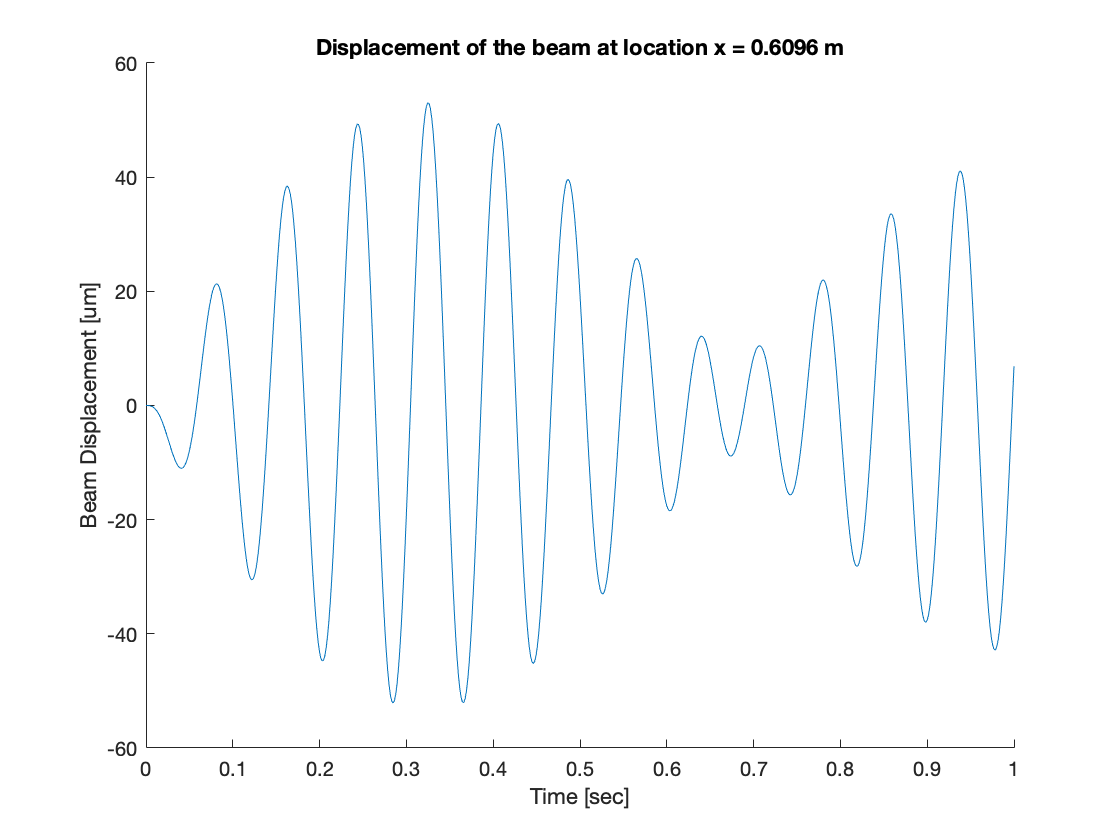

figure;                                                           % Create new figure
hold on;                                                          % Allow multiple plots
titleUnits = "m";                                                 % Initialize to meters default
ylabel("Beam Displacement [um]");                                 % Initialize to um default
if ~um                                                            % If the um checkbox was not selected...
    ylabel("Beam Displacement [in]");                             %      Then change to inches
end                                                               % 
if model.units == "English"                                       % If the model units are english...
    titleUnits = "ft";                                            %      Then change those units
end                                                               %
plot(t, Y_analytical);                                            % Plot results (inches)
xlabel("Time [sec]");                                             % Label x axis  
title(join(["Displacement of the beam at location x =",string(measurementLoc),titleUnits]," "));

## Frequency Response

This section calculates the magnitude and phase response of the system based on the relationship between the piezo voltage input to the beam's displacement output.

freq_range = linspace(1,floor(1.2*model.dynamics.freqs(end)),1000);            % Define frequency range
[mag, phase, num, den] = frequency_response(measurementLoc,model,freq_range);  % Obtain freqeuency response

sys = tf(num,den)

sys =
 
       -0.001999
  --------------------
  s^2 + 1.444 s + 5253
 
Continuous-time transfer function.



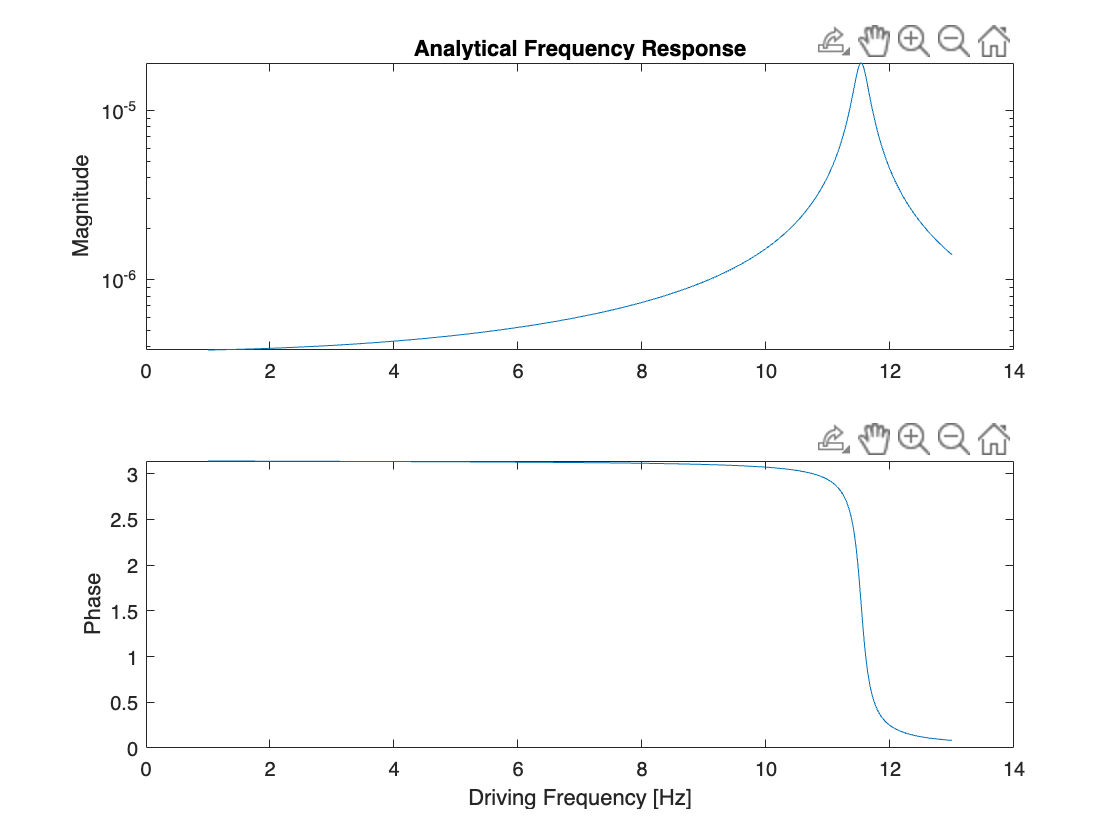


figure;                                                          
subplot(2,1,1);
semilogy(freq_range,mag)
ylabel("Magnitude");
title("Analytical Frequency Response");
subplot(2,1,2);
plot(freq_range,phase)
xlabel("Driving Frequency [Hz]");
ylabel("Phase");

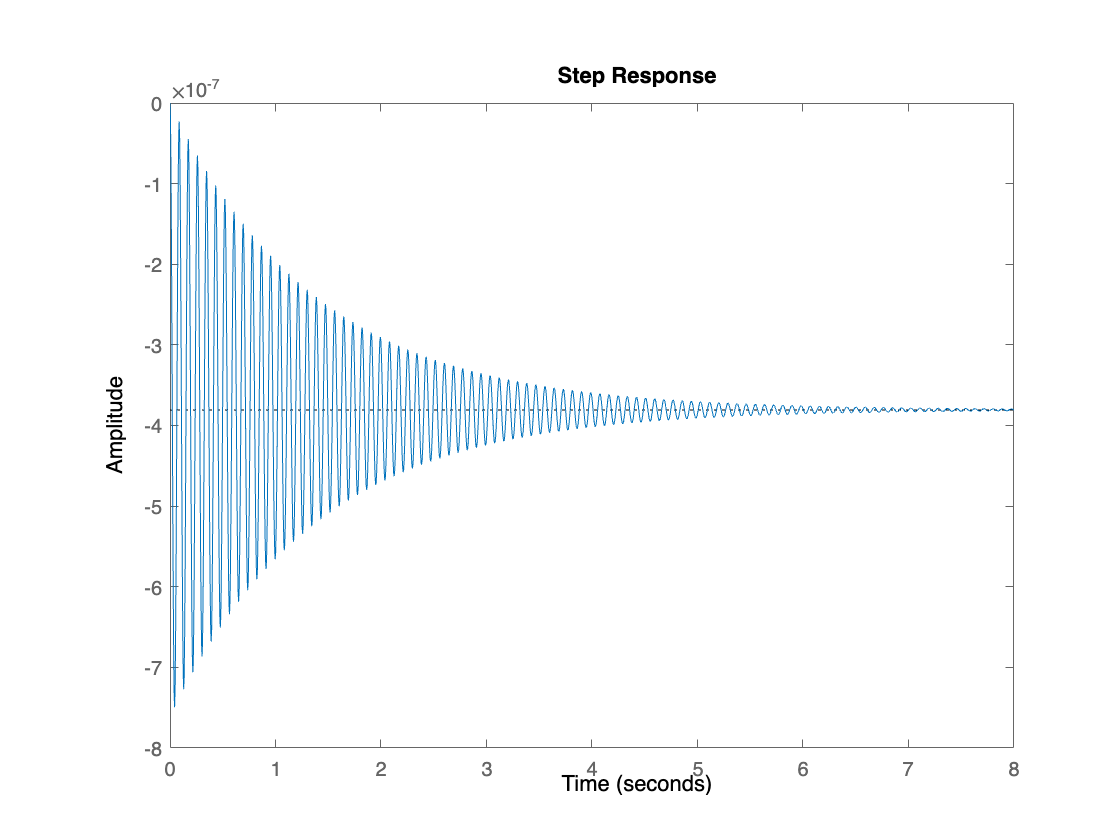


figure;
step(sys);